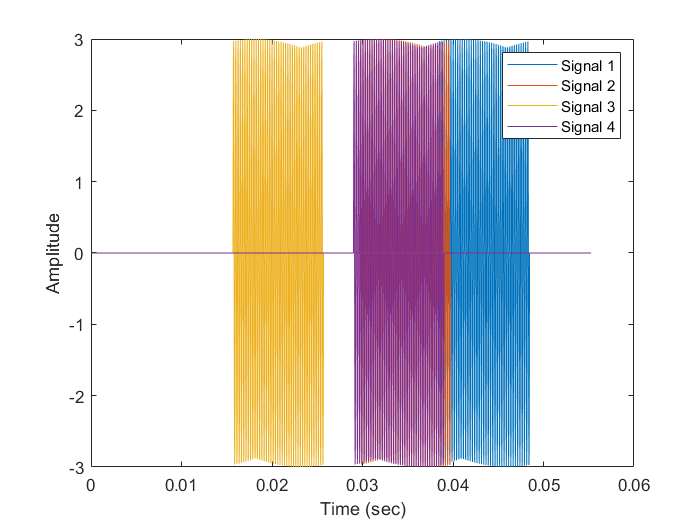

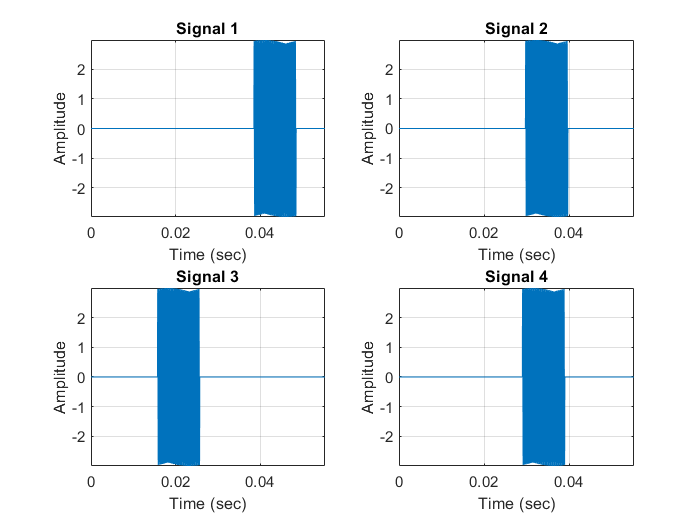

clear all

f=4000;
Fs=44100;
t=0:1/Fs:10e-3;
%n=[ 608 , 5905 , 6045 , 6015];
%n=[1587,1450,1123,882];
n=[1696,1311,692,1279];

s=3*sin(2*pi*f*t);
s1=[zeros(1, n(1)) , s, zeros(1,300)] ; 
s2=[zeros(1, n(2)) , s, zeros(1,length(s1)-n(2)-length(s))] ;
 
s3=[zeros(1, n(3)) , s, zeros(1,length(s1)-n(3)-length(s))];
s4=[zeros(1, n(4) ), s, zeros(1,length(s1)-n(4)-length(s))];

x1=0; y1=0; z1=0;
x2=5; y2=0; z2=5;
x3=5; y3=5; z3=5;
x4=0; y4=5; z4=0;


x=[x1,x2,x3,x4];
y=[y1,y2,y3,y4];
z=[z1,z2,z3,z4];
%x_real=35; y_real=24;z_real=20;
x_real=7; y_real=10;z_real=5;
semnale_timp(s1,s2,s3,s4,Fs);

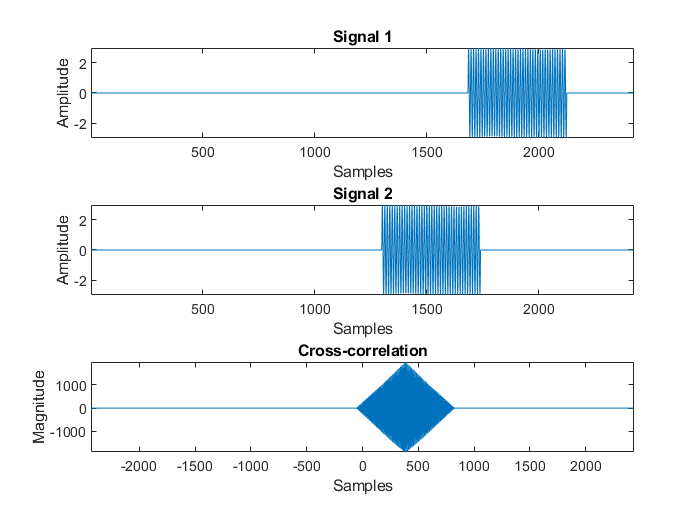

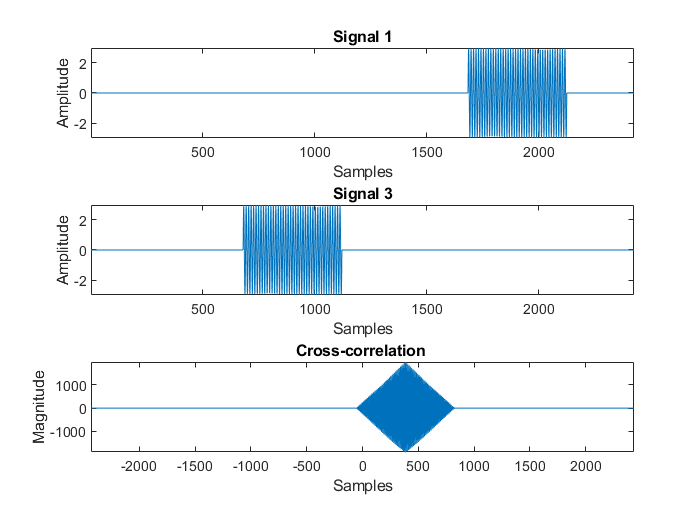

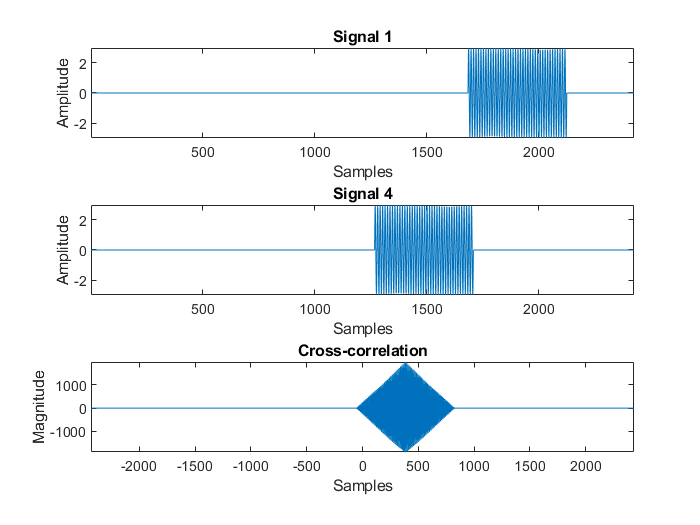

Contents();
%fft_semnale(s1,s2,s3,s4,Fs);
[tdoa12_cr , tdoa13_cr, tdoa14_cr] = corelatia(s1,s2,s3,s4,Fs);

xs = 6.0058

ys = 10.0137

zs = 6.0058

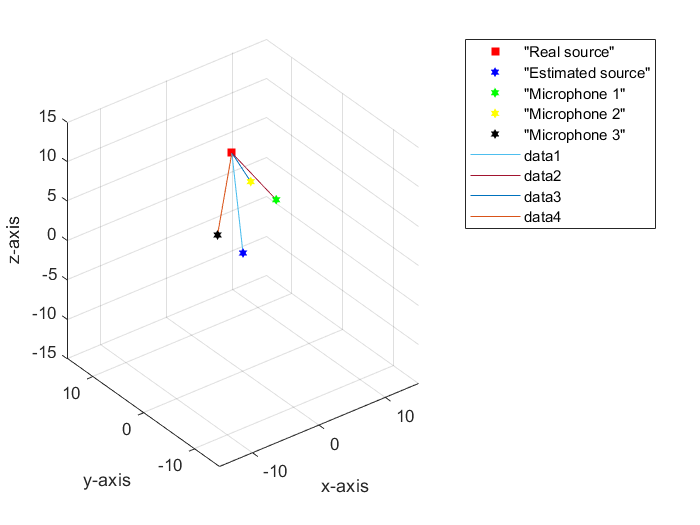

h =   Figure (23) with properties:

      Number: 23
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [489 343 560 420]
       Units: 'pixels'

  Show all properties


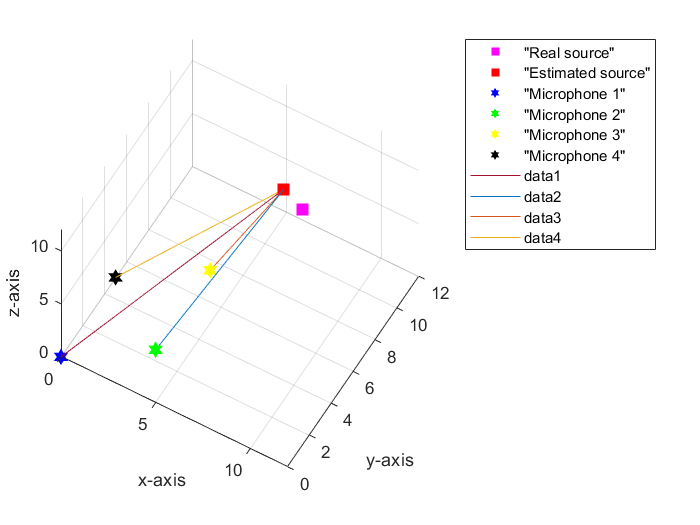

%[tdoa12_sp,tdoa13_sp,tdoa14_sp]= spectrograma_s(s1,s2,s3,s4,Fs);
%[tdoa12_rpa,tdoa13_rpa,tdoa14_rpa]=rpa(s1,s2,s3,s4,Fs);
%[tdoa12_wave,tdoa13_wave,tdoa14_wave]=wavelet_s(s1,s2,s3,s4,Fs)
%[xs_sp,ys_sp,zs_sp]=tdoa_sigur(tdoa12_sp,tdoa13_sp,tdoa14_sp,x1,x2,x3,x4,y1,y2,y3,y4,z1,z2,z3,z4,x_real,y_real,z_real);
[xs_cor,ys_cor,zs_cor]=tdoa_sigur(tdoa12_cr,tdoa13_cr,tdoa14_cr,x1,x2,x3,x4,y1,y2,y3,y4,z1,z2,z3,z4,x_real,y_real,z_real);

%[xs_rpa,ys_rpa,zs_rpa]=tdoa_sigur(tdoa12_rpa,tdoa13_rpa,tdoa14_rpa,x1,x2,x3,x4,y1,y2,y3,y4,z1,z2,z3,z4,x_real,y_real,z_real);
%[xs_wav,ys_wav,zs_wav]=tdoa_sigur(tdoa12_wave,tdoa13_wave,tdoa14_wave,x1,x2,x3,x4,y1,y2,y3,y4,z1,z2,z3,z4,x_real,y_real,z_real);

%Coordonata_x = [xs_sp,xs_cor,xs_rpa,xs_wav];
%Coordonata_y = [ys_sp,ys_cor,ys_rpa,xs_wav];
%Coordonata_z = [zs_sp,zs_cor,zs_rpa,zs_wav];
%rowNames = {'Spectrograma'; 'Cross-corelatia'; 'RPA' ; 'Transformata Wavelet'};
% T=table([xs_sp,xs_cor,xs_rpa,xs_wav],[ys_sp,ys_cor,ys_rpa,xs_wav],[zs_sp,zs_cor,zs_rpa,zs_wav]);
%T2= table([xs_sp,xs_cor,xs_rpa,xs_wav],[ys_sp,ys_cor,ys_rpa,xs_wav],[zs_sp,zs_cor,zs_rpa,zs_wav],'VariableNames',{'Coordonata x', 'Coordonata y', 'Coordonata z'} ,'RowNames', {'Spectrograma'; 'Cross-corelatia'; 'RPA' ; 'Transformata Wavelet'}) 
%writetable(T2,' rezultate.txt');




%A=["Cross-corelatia",xs_cor,ys_cor];
%B=["RPA",xs_rpa,ys_rpa];
%C=["Transformata wavelet",xs_wav,ys_wav];
%D=["Spectrograma",xs_sp,ys_sp];
%R=[A;B;C;D];
%A1=[xs_rpa,ys_rpa];
%fileID = fopen('coordonate_semnale_ideale.txt','w');
%fprintf(fileID, 'S-a detectat o sursa acustica la cooronatele:\n');
%fprintf(fileID,'%6s %12s\r\n','x','y');
%fprintf(fileID,'%6.2f %12.8f\r\n',A1);
%type coordonate2.txt;
%T=array2table(R,'VariableNames',{'Metoda','x','y'})
%send_email('cristina.popovici211@gmail.com','Sursa acustica detectata','S-a detectat o sursa acustica, deschideti fisierul pentru a viziona coordonatele:',{'C:\Users\Teo\Desktop\MATLAB\Licenta\coordonate_semnale_ideale.txt','C:\Users\Teo\Desktop\MATLAB\Licenta\Rezultate.jpg'})

